% Run this blog to get the array "taste_responsive"
% I know...This is not elegant

clear; 
clc;

 nostim_trials = 1:12;
 stim_trials = 13:24;

data_1618 = load('1618_early_stim_data.mat');
data_1681 = load('1681_early_stim_data.mat');
data_1722 = load('1722_early_stim_data.mat');
% data_1618 = load('1618_tonic_stim_data.mat');
% data_1681 = load('1681_tonic_stim_data.mat');
% data_1722 = load('1722_tonic_stim_data.mat');

[S_aligned_df, N_aligned_df, C_aligned_df, Q_aligned_df] = unpack_combine(data_1618.big_mat, ...
                                                                          data_1722.big_mat);
% Take 0-5s of the response (52:101). Convert data to 10 time bins of 500 ms
S_aligned_binned = bin_data(S_aligned_df(:,:, 52:101), 10);
N_aligned_binned = bin_data(N_aligned_df(:,:, 52:101), 10);
C_aligned_binned = bin_data(C_aligned_df(:,:, 52:101), 10);
Q_aligned_binned = bin_data(Q_aligned_df(:,:, 52:101), 10);

% Find the number of neurons responsive to each taste
% Use p-value of 0.005 (Bonferroni correction)
threshold = 1;

% Sweet
S_nostim_responsive = test_responsive(S_aligned_binned(:, nostim_trials, :), 0.005, threshold);
S_stim_responsive = test_responsive(S_aligned_binned(:, stim_trials, :), 0.005, threshold);
sum(S_nostim_responsive)

ans = 225

sum(S_stim_responsive)

ans = 237


% Salty
N_nostim_responsive = test_responsive(N_aligned_binned(:, nostim_trials, :), 0.005, threshold);
N_stim_responsive = test_responsive(N_aligned_binned(:, stim_trials, :), 0.005, threshold);
sum(N_nostim_responsive)

ans = 157

sum(N_stim_responsive)

ans = 170


% Sour
C_nostim_responsive = test_responsive(C_aligned_binned(:, nostim_trials, :), 0.005, threshold);
C_stim_responsive = test_responsive(C_aligned_binned(:, stim_trials, :), 0.005, threshold);
sum(C_nostim_responsive)

ans = 197

sum(C_stim_responsive)

ans = 196


% Bitter
Q_nostim_responsive = test_responsive(Q_aligned_binned(:, nostim_trials, :), 0.005, threshold);
Q_stim_responsive = test_responsive(Q_aligned_binned(:, stim_trials, :), 0.005, threshold);
sum(Q_nostim_responsive)

ans = 144

sum(Q_stim_responsive)

ans = 115


taste_responsive = find(S_nostim_responsive|S_stim_responsive| ...
                        N_nostim_responsive|N_stim_responsive| ...
                        C_nostim_responsive|C_stim_responsive| ...
                        Q_nostim_responsive|Q_stim_responsive);

% Load longer data for the actual analysis (overwriting some variables)

nostim_trials = 1:12;
stim_trials = 13:24;

data_1618 = load('1618_early_stim_data.mat');
data_1681 = load('1681_early_stim_data.mat');
data_1722 = load('1722_early_stim_data.mat');

% data_1618 = load('1618_tonic_stim_data.mat');
% data_1681 = load('1681_tonic_stim_data.mat');
% data_1722 = load('1722_tonic_stim_data.mat');


[S_aligned_df, N_aligned_df, C_aligned_df, Q_aligned_df] = unpack_combine(data_1618.big_mat, ...
                                                                          data_1722.big_mat);

% Convert data to 25 time bins of 500 ms
S_aligned = S_aligned_df;
N_aligned = N_aligned_df;
C_aligned = C_aligned_df;
Q_aligned = Q_aligned_df;

window = 51:100;
timepoint_per_trial_type = length(window)*12;

S_nostim = S_aligned(taste_responsive, nostim_trials, window);
N_nostim = N_aligned(taste_responsive, nostim_trials, window);
C_nostim = C_aligned(taste_responsive, nostim_trials, window);
Q_nostim = Q_aligned(taste_responsive, nostim_trials, window);

S_stim = S_aligned(taste_responsive, stim_trials, window);
N_stim = N_aligned(taste_responsive, stim_trials, window);
C_stim = C_aligned(taste_responsive, stim_trials, window);
Q_stim = Q_aligned(taste_responsive, stim_trials, window);

% trial means, transposed (bins x cells)
S_nostim_trial_mean = squeeze(mean(S_nostim, 2))';
N_nostim_trial_mean = squeeze(mean(N_nostim, 2))';
C_nostim_trial_mean = squeeze(mean(C_nostim, 2))';
Q_nostim_trial_mean = squeeze(mean(Q_nostim, 2))';

S_stim_trial_mean = squeeze(mean(S_stim, 2))';
N_stim_trial_mean = squeeze(mean(N_stim, 2))';
C_stim_trial_mean = squeeze(mean(C_stim, 2))';
Q_stim_trial_mean = squeeze(mean(Q_stim, 2))';

trial_mean_design_mat = cat(1, S_nostim_trial_mean, ...
                                N_nostim_trial_mean, ...
                                C_nostim_trial_mean, ...
                                Q_nostim_trial_mean, ...
                                S_stim_trial_mean, ...
                                N_stim_trial_mean, ...
                                C_stim_trial_mean, ...
                                Q_stim_trial_mean);

cell_count = size(S_nostim, 1);
total_timepoints = size(S_nostim, 2) * size(S_nostim, 3);
S_nostim_reshaped = reshape(S_nostim, cell_count, total_timepoints)';
N_nostim_reshaped = reshape(N_nostim, cell_count, total_timepoints)';
C_nostim_reshaped = reshape(C_nostim, cell_count, total_timepoints)';
Q_nostim_reshaped = reshape(Q_nostim, cell_count, total_timepoints)';

S_stim_reshaped = reshape(S_stim, cell_count, total_timepoints)';
N_stim_reshaped = reshape(N_stim, cell_count, total_timepoints)';
C_stim_reshaped = reshape(C_stim, cell_count, total_timepoints)';
Q_stim_reshaped = reshape(Q_stim, cell_count, total_timepoints)';

all_trials_design_mat = cat(1, S_nostim_reshaped, ...
    N_nostim_reshaped, ...
    C_nostim_reshaped, ...
    Q_nostim_reshaped, ...
    S_stim_reshaped, ...
    N_stim_reshaped, ...
    C_stim_reshaped, ...
    Q_stim_reshaped);


clf
% Perform PCA
[coeff, score, ~, ~, explained] = pca(all_trials_design_mat);

Unrecognized function or variable 'all_trials_design_mat'.


% Define colors for each class
colors = [
    0.68, 0.85, 0.90; % Light blue
    0.56, 0.93, 0.56; % Light green
    0.82, 0.71, 0.55; % Light brown
    0.80, 0.60, 0.79; % Light purple
    0, 0, 0.55;       % Dark blue
    0, 0.39, 0;       % Dark green
    0.55, 0.27, 0.07; % Dark brown
    0.48, 0.06, 0.89  % Dark purple
];

% Plot the top 3 principal components
figure;
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    % class_data = score((i-1)*timepoint_per_trial_type+1:i*timepoint_per_trial_type, 1:3);
    class_data = score((i-1)*50+1:i*50, 1:3);
    % % Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 50, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k', ...
             'DisplayName', sprintf('Class %d', i));
    % 
    % Plot the line connecting points in the i-th class
    % plot3(class_data(:, 1), class_data(:, 2), class_data(:, 3), ...
    %     'Color', colors(i, :), 'LineWidth', 1.5, ...
    %     'DisplayName', sprintf('Class %d', i));
end

% Label the axes
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

% Add legend and title
legend({'S no stim', 'N no stim', 'C no stim', 'Q no stim', ...
        'S stim', 'N stim', 'C stim', 'Q stim'}, 'Location', 'best');
title('PCA Results with Top 3 Principal Components');
grid on;
hold off;

view(3);

% Average response during 1-4 sec post stimulus cell x trials
S_bin_mean = squeeze(mean(S_aligned_df(:,:, 61:85), 3));
N_bin_mean = squeeze(mean(N_aligned_df(:,:, 61:85), 3));
C_bin_mean = squeeze(mean(C_aligned_df(:,:, 61:85), 3));
Q_bin_mean = squeeze(mean(Q_aligned_df(:,:, 61:85), 3));

% Max val normalization
S_bin_mean = S_bin_mean ./ max_val;
N_bin_mean = N_bin_mean ./ max_val;
C_bin_mean = C_bin_mean ./ max_val;
Q_bin_mean = Q_bin_mean ./ max_val;

S_bin_mean_nostim = S_bin_mean(cell_list_for_analysis, nostim_trials, :);
N_bin_mean_nostim = N_bin_mean(cell_list_for_analysis, nostim_trials, :);
C_bin_mean_nostim = C_bin_mean(cell_list_for_analysis, nostim_trials, :);
Q_bin_mean_nostim = Q_bin_mean(cell_list_for_analysis, nostim_trials, :);

S_bin_mean_stim = S_bin_mean(cell_list_for_analysis, stim_trials, :);
N_bin_mean_stim = N_bin_mean(cell_list_for_analysis, stim_trials, :);
C_bin_mean_stim = C_bin_mean(cell_list_for_analysis, stim_trials, :);
Q_bin_mean_stim = Q_bin_mean(cell_list_for_analysis, stim_trials, :);


bin_mean_design_mat = cat(1,S_bin_mean_nostim', ...
    N_bin_mean_nostim', ...
    C_bin_mean_nostim', ...
    Q_bin_mean_nostim', ...
    S_bin_mean_stim', ...
    N_bin_mean_stim', ...
    C_bin_mean_stim', ...
    Q_bin_mean_stim');

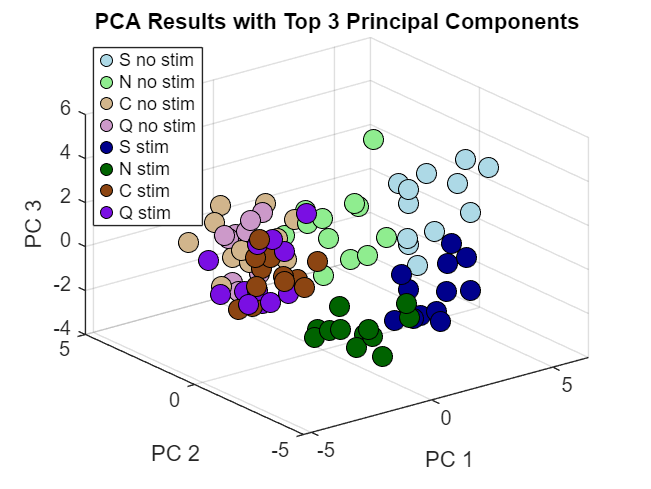



% Perform PCA
[coeff, score, ~, ~, explained] = pca(bin_mean_design_mat);

% Define colors for each class
colors = [
    0.68, 0.85, 0.90; % Light blue
    0.56, 0.93, 0.56; % Light green
    0.82, 0.71, 0.55; % Light brown
    0.80, 0.60, 0.79; % Light purple
    0, 0, 0.55;       % Dark blue
    0, 0.39, 0;       % Dark green
    0.55, 0.27, 0.07; % Dark brown
    0.48, 0.06, 0.89  % Dark purple
];

% Plot the top 3 principal components
figure;
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    class_data = score((i-1)*12+1:i*12, 1:3);
    
    % Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 100, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k', ...
             'DisplayName', sprintf('Class %d', i));

    % % Plot the line connecting points in the i-th class
    % plot3(class_data(:, 1), class_data(:, 2), class_data(:, 3), ...
    %     'Color', colors(i, :), 'LineWidth', 1.5, ...
    %     'DisplayName', sprintf('Class %d', i));
end

% Label the axes
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

% Add legend and title
legend({'S no stim', 'N no stim', 'C no stim', 'Q no stim', ...
        'S stim', 'N stim', 'C stim', 'Q stim'}, 'Location', 'best');
title('PCA Results with Top 3 Principal Components');
grid on;
hold off;

view(3);

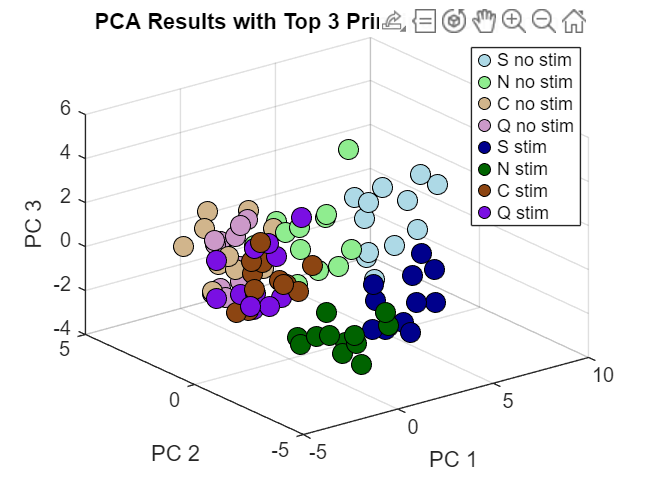

% Projecting trial-preserved data onto PCs defined using time-preserved data.
bin_mean_mat_projected = bin_mean_design_mat * coeff(:, 1:6);

% Define colors for each class
colors = [
    0.68, 0.85, 0.90; % Light blue
    0.56, 0.93, 0.56; % Light green
    0.82, 0.71, 0.55; % Light brown
    0.80, 0.60, 0.79; % Light purple
    0, 0, 0.55;       % Dark blue
    0, 0.39, 0;       % Dark green
    0.55, 0.27, 0.07; % Dark brown
    0.48, 0.06, 0.89  % Dark purple
];

trial_type_label = repelem(1:8, 12);

% Plot the top 3 principal components
figure;
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    trial_type = (trial_type_label == i);
    class_data = bin_mean_mat_projected(trial_type, 1:3);
    
    % Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 100, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k', ...
             'DisplayName', sprintf('Class %d', i));

    % % Plot the line connecting points in the i-th class
    % plot3(class_data(:, 1), class_data(:, 2), class_data(:, 3), ...
    %     'Color', colors(i, :), 'LineWidth', 1.5, ...
    %     'DisplayName', sprintf('Class %d', i));
end

% Label the axes
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

% Add legend and title
legend({'S no stim', 'N no stim', 'C no stim', 'Q no stim', ...
        'S stim', 'N stim', 'C stim', 'Q stim'}, 'Location', 'best');
title('PCA Results with Top 3 Principal Components');
grid on;
hold off;

view(3);

% Find the mean point of palatable tastes (no stim)
S_and_N_labels = trial_type_label == 1 | trial_type_label == 2;
palatable_mean_point = mean(bin_mean_mat_projected(S_and_N_labels, :), 1);

% Find the mean point of unpalatable tastes (no stim)
C_and_Q_labels = trial_type_label == 3 | trial_type_label == 4;
unpalatable_mean_point = mean(bin_mean_mat_projected(C_and_Q_labels, :), 1);

% palatability axis goes through the palatable and unpalatable mean points
palatability_vector = palatable_mean_point - unpalatable_mean_point;
% Divide by norm to make it a unit vector
palatability_axis = palatability_vector/norm(palatability_vector);

palatability_axis_center = (palatable_mean_point + unpalatable_mean_point)/2;
center_projected = palatability_axis_center * palatability_axis';
scaling_factor = sqrt(sum((palatable_mean_point - palatability_axis_center).^2));
p_projected = palatable_mean_point * palatability_axis';
(p_projected - center_projected) / scaling_factor

ans = 1

up_projected = unpalatable_mean_point * palatability_axis';
(up_projected - center_projected) / scaling_factor

ans = -1


bin_mean_p_projected = (bin_mean_mat_projected - palatability_axis_center) * palatability_axis';
bin_mean_pscore = bin_mean_p_projected / scaling_factor;

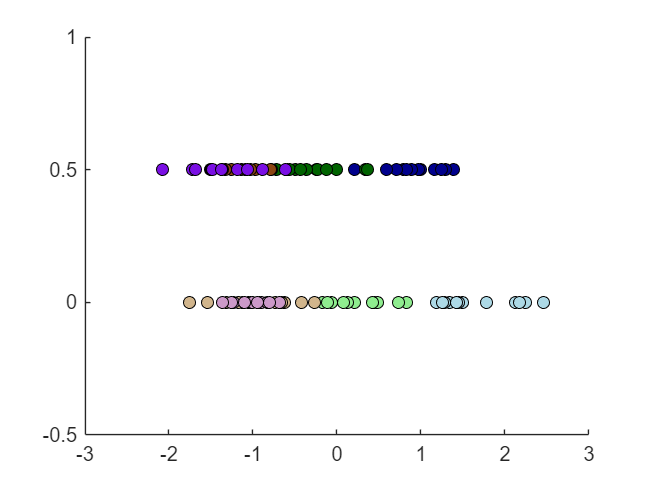

pscore_mat = zeros(12, 8); % 12 trials per trial type
clf
hold on

for i = 1:4
    trial_type = (trial_type_label == i);
    scatter(bin_mean_pscore(trial_type), zeros(1, 12), ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');

    pscore_mat(:, i) = bin_mean_pscore(trial_type);
end

for i = 5:8
    trial_type = (trial_type_label == i);
        scatter(bin_mean_pscore(trial_type), ones(1, 12) *0.5, ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    
    pscore_mat(:, i) = bin_mean_pscore(trial_type);
end

ylim([-0.5, 1])

hold off

col_names = ["S nostim", "N nostim", "C nostim", "Q nostim",...
             "S stim", "N stim", "C stim", "Q stim"]

col_names = 1×8 string array
    "S nostim"    "N nostim"    "C nostim"    "Q nostim"    "S stim"    "N stim"    "C stim"    "Q stim"


pscore_tab = array2table(pscore_mat,"VariableNames", col_names);

filename = "Early stim PCA palatability score (cohort 1 + 3).xlsx";
writetable(pscore_tab, filename);

% Calculate the direction each taste shifted.
S_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 1), :), 1);
N_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 2), :), 1);
C_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 3), :), 1);
Q_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 4), :), 1);

S_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 5), :), 1);
N_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 6), :), 1);
C_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 7), :), 1);
Q_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 8), :), 1);

S_shift_vector = S_stim_mean_point - S_nostim_mean_point;
N_shift_vector = N_stim_mean_point - N_nostim_mean_point;
C_shift_vector = C_stim_mean_point - C_nostim_mean_point;
Q_shift_vector = Q_stim_mean_point - Q_nostim_mean_point;

mean_shift_vector = (S_shift_vector + N_shift_vector + C_shift_vector + Q_shift_vector) / 4;

% Calculate the angle between the shift vector and palatability axis
dot_product = dot(mean_shift_vector, palatability_axis);
theta_shift_palatability = acos(dot_product / norm(mean_shift_vector) * norm(palatability_axis));
theta_shift_palatability_deg = 180 - rad2deg(theta_shift_palatability);